# Homework 8

## Problem 5.1: Frequency estimation using Pisarenko's method

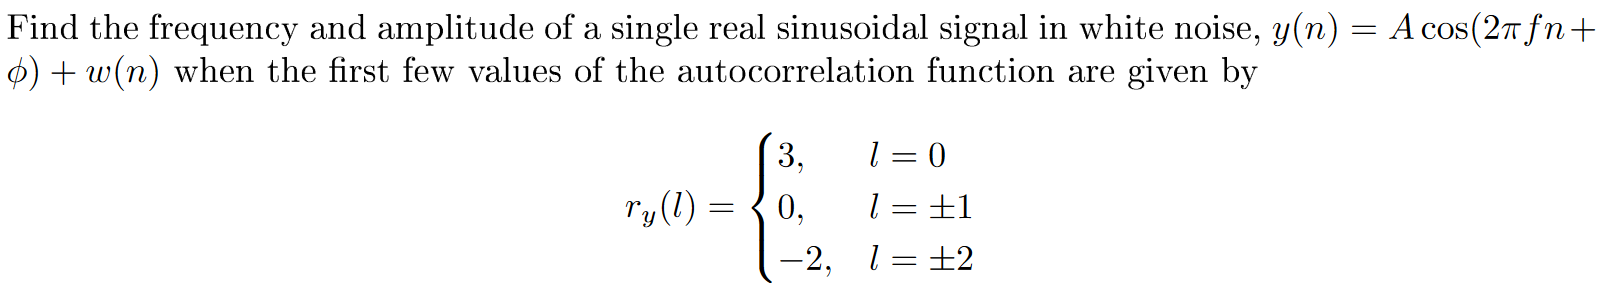

clear variables;

***Step 1***: Compute the autocorrelation matrix ${\mathbf{R}}_{\mathrm{yy}}$

p = 1;
r_yy = [3, 0, -2];
R_yy = toeplitz(r_yy)

R_yy =      3     0    -2
     0     3     0
    -2     0     3


***Step 2:*** Find the minimum eigenvalue and the corresponding eigenvector. The elements of this eigenvector is the parameters of the $\mathrm{ARMA}\left(2p,2p\right)$ model.

[eigvecs, eigvals] = eigs(R_yy, size(R_yy, 1), 'smallestreal')

eigvecs =    -0.7071         0   -0.7071
         0    1.0000         0
   -0.7071         0    0.7071


eigvals =     1.0000         0         0
         0    3.0000         0
         0         0    5.0000


min_eig_vec = eigvecs(:, 1)

min_eig_vec =    -0.7071
         0
   -0.7071


***Step 3:*** Find the frequencies $\left\lbrace \;f_i \;\right\rbrace$ of the sinusoids. This can be done by computing the roots of the polynomial $A\left(z\right)$ in (14.5.4). This polynomial has $2p$ poles on the unit circle which correspond to the frequencies of the system.

        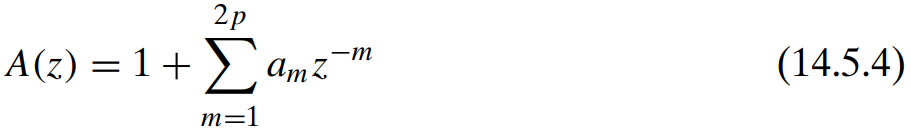

Since the given estimating the frequency of a signal real sinusoid, we have:

        
$$A\left(z\right)=1+a_1 z^{-1} +a_2 z^{-2}$$


The parameters $\left\lbrace a_0 ,a_1 ,a_2 \right\rbrace$ corresponds to the eigenvector of the smallest eigenvalue:

% By definition a_0 = 1
a = min_eig_vec / min_eig_vec(1) 

a =      1
     0
     1


This means we have following IIR filter:

        
$$A\left(z\right)=1+z^{-2}$$


We know that the polynomial $A\left(z\right)$ in (14.5.4) has $2p=2\cdot 1=2$ poles on the unit circle. We can find the poles by finding the roots of the system $A\left(z\right)=1+z^{-2}$:

z = roots(a)

z =    0.0000 + 1.0000i
   0.0000 - 1.0000i


The poles on the unit circle correspond to the frequencies of the system.

The two poles are complex conjucate of each other. Since $z=A\;e^{\mathrm{j2}\pi f}$, we can find the frequency by the angle:

        $\angle z=2\pi f$  and $f=\frac{\angle z}{2\pi }$

% The poles come in pairs. Each pair is complex conjugate
% of one another. Only use one of them and find the absolution value.
f1 = abs(angle(z(2))) / (2*pi)

f1 = 0.2500

**Step 4:** Solve Eq. (14.5.11) to find the signal powers $\left\lbrace P_i \right\rbrace$

        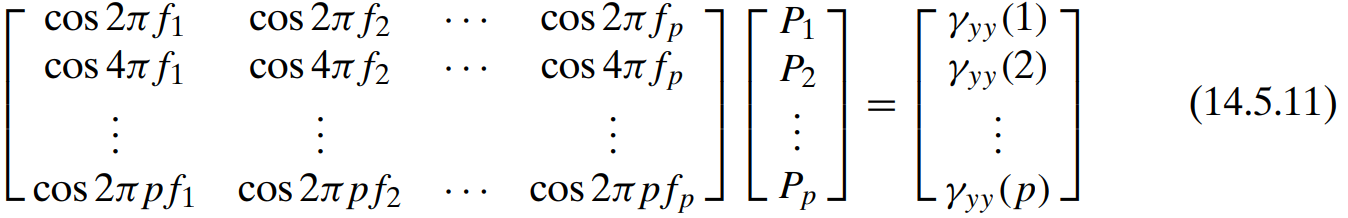

Since we only have one frequency, the equation becomes:

        $\mathrm{cos}\left(2\pi f_1 \right)P_1 =\gamma_{\mathrm{yy}} \left(1\right)$ where $\gamma_{\textrm{yy}} \left(1\right)$ is the second autocorrelation value:

We want to find $P_1$:  

        
$$P_1 =\frac{\gamma_{\textrm{yy}} \left(1\right)}{\cos \left(2\pi f_1 \right)}$$
  

P1 = r_yy(2) / cos(2*pi*f1)

P1 = 0

From section 14.5.1, we are given:

        
$$P_i =\frac{A_i^2 }{2}$$


This allows us to estimate the amplitude $A_i$ given $P_i$:

        
$$A_i =\sqrt{2P_i }$$


A1 = sqrt(2*P1)

A1 = 0

So frequency is $f=0\ldotp 25$ and the amplitude is 0. **Why?**

[F, A] = pisarenko(r_yy, 1)

F = 0.2500

A = 0

## Problem 5.2: Pisarenko

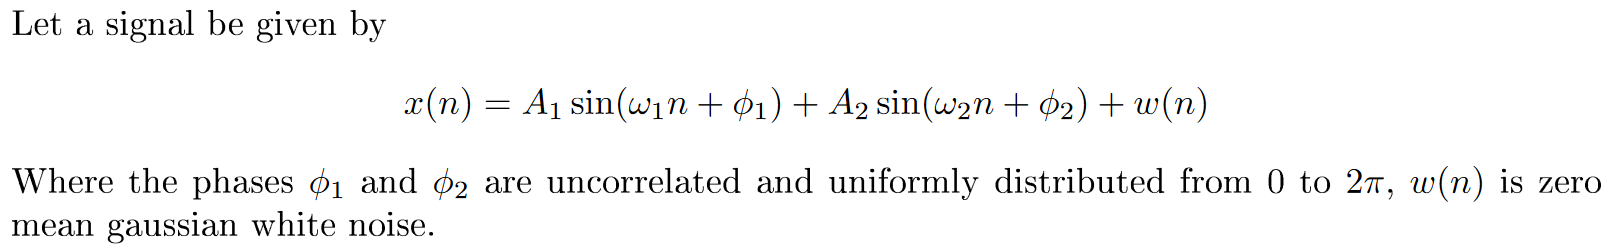

clear variables;

### 0) Preliminary, compute the autocorrelation function of a sine signal:

In ADSI Problem 4.4, we found that the autocorrelation of a complex sinusoid givey by $y\left(n\right)=A\;e^{j\left(\omega n+\phi \right)}$ where $A$ and $\omega$ are real constants and $\phi$ is a random variable with $\phi ~U\left(0,2\pi \right)$ is:

        
$$r_{\mathrm{yy}} \left(\ell \right)=A^2 \;e^{j\omega \ell }$$


To use this result, we need to convert the given signal in this problem to complex exponential signal.

A complex exponential signal is always formed by the sum of two real signals:

        
$$Ae^{j\omega n} =A\;\mathrm{cos}\left(\omega n\right)+j\;A\;\mathrm{sin}\left(\omega n\right)$$


Therefore, we know that:

        
$$\mathrm{sin}\left(\omega \right)=\frac{1}{2j}e^{j\omega } -\frac{1}{2j}e^{-j\omega }$$


Using this relation, we can rewrite a real signal $A\;\mathrm{sin}\left(\omega n+\phi \right)$ as:

        
$$z\left(n\right)=A\;\mathrm{sin}\left(\omega n+\phi \right)$$


        
$$z\left(n\right)=\frac{A}{2j}e^{j\left(\omega n+\phi \right)} -\frac{A}{2j}e^{-j\left(\omega n+\phi \right)}$$


To compute the autocorrelation function, we square the magnitude, remove the phase and replace $n$ with $\ell$:

        
$$r_{\mathrm{zz}} \left(\ell \right)={\left(\frac{A}{2j}\right)}^2 e^{j\omega \ell } -{\left(\frac{A}{2j}\right)}^2 e^{-j\omega \ell }$$


We know that${\left(2j\right)}^2 =2^2 \cdot j^2 =-4$ because $j=\sqrt{-1}$ so $j^2 =-1$

        
$$r_{\textrm{zz}} \left(\ell \right)=\frac{A^2 }{-4}e^{j\omega \ell } -\frac{A^2 }{-4}e^{-j\omega \ell }$$


        
$$r_{\textrm{zz}} \left(\ell \right)=-\frac{A^2 }{4}e^{j\omega \ell } +\frac{A^2 }{4}e^{-j\omega \ell }$$


We want to make the autocorrelation function in terms of $\mathrm{cos}\left(\cdot \right)$, we rewrite the expression as follows:

        
$$r_{\textrm{zz}} \left(\ell \right)=\left(-\frac{A^2 }{2}\right)\cdot \frac{1}{2}\left(e^{j\omega \ell } +e^{-j\omega \ell } \right)$$


Since $\mathrm{cos}\left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$, we can rewrite the expression as:

        
$$r_{\textrm{zz}} \left(\ell \right)=-\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


Thus, the autocorrelation function of a real signal $z\left(n\right)=A\;\mathrm{sin}\left(\omega n+\phi \right)$ is

        
$$r_{\textrm{zz}} \left(\ell \right)=-\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


### 1) Calculate the autocorrelation function

The autocorrelation function of a real signal $z\left(n\right)=A\;\mathrm{sin}\left(\omega n+\phi \right)$ where $A$ and $\omega$ are real constants and $\phi$ is a random variable with $\phi ~U\left(0,2\pi \right)$ is:

        
$$r_{\textrm{zz}} \left(\ell \right)=-\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


The autocorrelation function of white noise Gassian noise with zero mean and variance $\sigma_w^2$ is:

        
$$r_{\mathrm{ww}} \left(\ell \right)=\sigma_w^2 \delta \left(\ell \right)$$


In this problem, we are given:

        

The autocorrelation function of the signal $x\left(n\right)$ given in this problem is:

        
$$r_{\mathrm{xx}} \left(\ell \right)=-\frac{{A_1 }^2 }{2}\cos \left(\omega_1 \ell \right)-\frac{{A_2 }^2 }{2}\cos \left(\omega_2 \ell \right)+\sigma_w^2 \delta \left(\ell \right)$$


or

        
$$r_{\textrm{xx}} \left(\ell \right)=-\frac{{A_1 }^2 }{2}\cos \left(2\pi f_1 \ell \right)-\frac{{A_2 }^2 }{2}\cos \left(2\pi f_2 \ell \right)+\sigma_w^2 \delta \left(\ell \right)$$


### 2) Choose appropriate values for the amplitudes and frequencies and for the noise power

We choose following values:

        
$$A_1 =4,A_2 =8,f_1 =\frac{1}{4\pi },f_2 =\frac{1}{\pi },\sigma_w^2 =1$$


### 3) Calculate the eigenvalues of the autocorrelation matrix as a function of its size and compare with your expectation

% The values that we chose in problem 5.2
A1=4;  A2=8;  f1=1/(4*pi);  f2=1/pi;  wvar=1;

% The size of the autocorrelation sequence
% L = 64;
% l = 0:L-1;
% r_xx = -((A1^2/2) * cos(2*pi*f1*l)) - ((A2^2/2) * cos(2*pi*f2*l)) + wvar
ell_seq = 0:pi/4:2*pi;

L = numel(ell_seq);

% Initialise the autocorrelation sequence with zeros.
% This becomes very important especially when 
% the size of the ACRZ (the ell variable) is changed
r_xx = zeros(L, 1);

% Compute the autocorrelation sequence based on the
% autocorrelation function derived in problem 1)
for i = 1:L
    ell = ell_seq(i);
    r_xx(i) = -((A1^2)/2 * cos(2*pi*f1*ell)) - ((A2^2)/2 * cos(2*pi*f2*ell)) + wvar;
end
r_xx

r_xx =   -39.0000
   -6.3910
   27.3431
   -2.0615
  -31.0000
    4.0615
   38.6569
    8.3910
  -23.0000



% Compute the autocorrelation matrix
R_xx = toeplitz(r_xx)

R_xx =   -39.0000   -6.3910   27.3431   -2.0615  -31.0000    4.0615   38.6569    8.3910  -23.0000
   -6.3910  -39.0000   -6.3910   27.3431   -2.0615  -31.0000    4.0615   38.6569    8.3910
   27.3431   -6.3910  -39.0000   -6.3910   27.3431   -2.0615  -31.0000    4.0615   38.6569
   -2.0615   27.3431   -6.3910  -39.0000   -6.3910   27.3431   -2.0615  -31.0000    4.0615
  -31.0000   -2.0615   27.3431   -6.3910  -39.0000   -6.3910   27.3431   -2.0615  -31.0000
    4.0615  -31.0000   -2.0615   27.3431   -6.3910  -39.0000   -6.3910   27.3431   -2.0615
   38.6569    4.0615  -31.0000   -2.0615   27.3431   -6.3910  -39.0000   -6.3910   27.3431
    8.3910   38.6569    4.0615  -31.0000   -2.0615   27.3431   -6.3910  -39.0000   -6.3910
  -23.0000    8.3910   38.6569    4.0615  -31.0000   -2.0615   27.3431   -6.3910  -39.0000


### 4) Use the Pisarenko method to calculate the spectrum and compare with the expected results

[F, A] = pisarenko(r_xx, 2)

F =     0.0878
    0.4166


A =     7.0875
    8.0111


## Problem 5.3: Frequency resolution of the Pisarenko method  

*In this problem the goal is to investigate the frequency resolution of the Pisarenko method. We will use your two-sinusoids-in-white-noise model from the previous problem:*

clear variables;

### 1) Create two realisations, use the Pisarenko method to compute the spectrum and comment on the stability of the method

***a) Create a number of short realizations, i.e. N=64 or N=128 with different initial phases.***

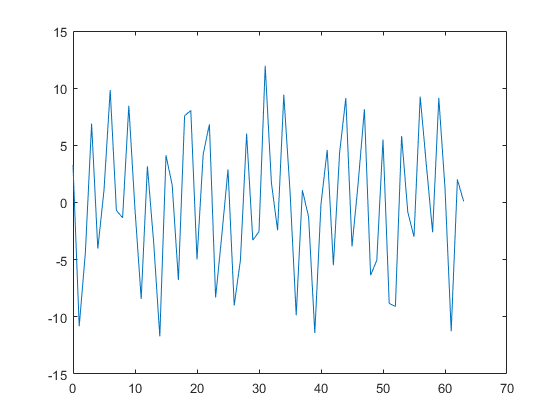

% The values that we chose in problem 5.2
A1=4;  A2=8;  f1=1/(4*pi);  f2=1/pi;  wvar=1;

N = 64;
n = 0:N-1;

% Generate phi(1) and phi(2) from U(0, 2*pi)
phi = 2*pi*rand(1, 2);

% Generate noise signal with chosen variance
wn = sqrt(wvar) * randn(1, N);

% Generate the signal
x1 = A1 * sin(2*pi*f1*n + phi(1)) + A2 * sin(2*pi*f2*n + phi(2)) + wn;
plot(n, x1)

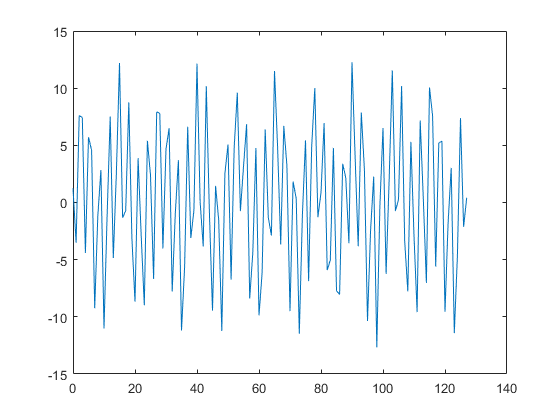

N = 128;
n = 0:N-1;

% Generate phi(1) and phi(2) from U(0, 2*pi)
phi = 2*pi*rand(1, 2);

% Generate noise signal with chosen variance
wn = sqrt(wvar) * randn(1, N);

% Generate the signal
x2 = A1 * sin(2*pi*f1*n + phi(1)) + A2 * sin(2*pi*f2*n + phi(2)) + wn;
plot(n, x2)

***b) Use the Pisarenko method to compute the spectrum of the two realizations.***

p = 2; % Number of sinusoids in the signals

% Compute the autocorrelation sequence
[r_x1, lags] = xcorr(x1', 'biased');

% Compute the autocorrelation matrix from rx(0)
mid_index = ceil(numel(lags)/2);
[F, A] = pisarenko(r_x1(mid_index:end), p)

F =     0.3181
    0.0848


A =     7.6030
    3.6948


% Compute the autocorrelation sequence
[r_x2, lags] = xcorr(x2', 'biased');

% Compute the autocorrelation matrix from rx(0)
mid_index = ceil(numel(lags)/2);
[F, A] = pisarenko(r_x2(mid_index:end), p)

F =     0.3184
    0.0801


A =     7.8878
    3.8477


***c) Comment on the stability of the Pisarenko method***

### 2) Can shifts in frequency be measured?

*Create a number of short realizations where one of the frequencies is shifted 1% up or down. Can this shift in frequency be measured?  *

### 3) How small a frequency shift can you measure with a sequence length of *N*=128?

## Problem 5.4: Pisarenko and coloured noise

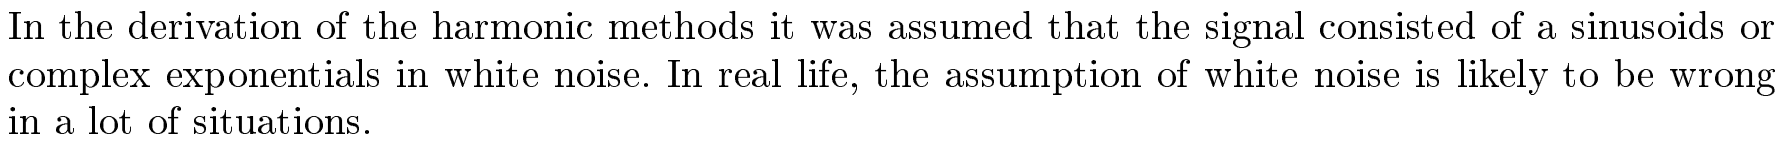

clear variables;

### 1) Create a MATLAB model of a sinusoidal signal in white, slightly coloured and very coloured noise.

When the power spectral density of the noise is not uniform across the entire frequency spectrum, it is called colored noise.

% The values that we chose in problem 5.2
A1=4;      f1=1/(4*pi);   phi1 = 2*pi*rand(); % Phase ~ U(0, 2pi)

N = 128;   n = 0:N-1;

% Generate a signal with white noise
w1 = step(dsp.ColoredNoise('InverseFrequencyPower', 0, 'SamplesPerFrame', numel(n)))';
x1 = A1 * cos(2*pi*f1*n + phi1) + w1;

% Generate a signal with slightly coloured noise
w2 = step(dsp.ColoredNoise('InverseFrequencyPower', 0.4, 'SamplesPerFrame', numel(n)))';
x2 = A1 * cos(2*pi*f1*n + phi1) + w2;

% Generate a signal with highly coloured noise
w3 = step(dsp.ColoredNoise('InverseFrequencyPower', 2, 'SamplesPerFrame', N));
x3 = A1 * cos(2*pi*f1*n + phi1) + w2;

### 2) Compare the eigenvalues of the autocorrelation matrix for the three different scenarios.  

L = 3; % The length of ACRS
[r_x1, ~] = xcorr(x1, L, 'biased');
R_x1 = toeplitz(r_x1(L+1:end));
eigs(R_x1, size(R_x1, 1), 'smallestreal')

ans =     1.0040
    1.1728
   10.2108
   26.2975


[r_x2, ~] = xcorr(x2, L, 'biased');
R_x2 = toeplitz(r_x2(L+1:end));
eigs(R_x2, size(R_x2, 1), 'smallestreal')

ans =     0.9099
    0.9534
   10.0999
   26.8529


[r_x3, ~] = xcorr(x3, L, 'biased');
R_x3 = toeplitz(r_x3(L+1:end));
eigs(R_x3, size(R_x3, 1), 'smallestreal')

ans =     0.9099
    0.9534
   10.0999
   26.8529


### 3) Calculate the Pisarenko spectra and discuss whether Pisarenko is useful when the noise is coloured.

[F1, A1] = pisarenko(r_x1', 1)

F1 = 0

A1 = 3.0094

[F2, A2] = pisarenko(r_x2', 1)

F2 = 0

A2 = 3.0827

[F3, A3] = pisarenko(r_x3', 1)

F3 = 0

A3 = 3.0827

## [✔] Problem 5.5: Pisarenko, wrong choise of eigenvector

*In example 14.5.1 from the note the autocorrelation matrix for a process consisting of a single sinusoid in additive white noise is given as  *

        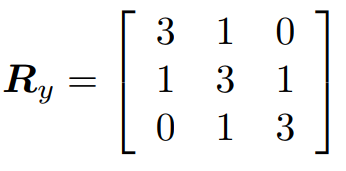

*The example proceeds to find *$f_1 =\frac{1}{8}$

### 1) How does the use of a wrong eigenvalue influence the solution?

*Repeat the example, but use the two other eigenvalues as starting points. How does the use of a wrong eigenvalue influence the solution?*

***Step 1***: Compute the autocorrelation matrix ${\mathbf{R}}_{\mathrm{yy}}$

r_yy = [3, 1, 0];
R_yy = toeplitz(r_yy);
[eigvecs, eigvals] = eigs(R_yy, size(R_yy, 1), 'smallestreal');

% Choose which eigenvalues is used for the calculations.
% The eigenvalues are sorted in increasing order, so
% the first eigenvalue is the smallest.
chosen_eig_idx = 1;

***Step 2:*** Find the minimum eigenvalue and the corresponding eigenvector. The elements of this eigenvector is the parameters of the $\mathrm{ARMA}\left(2p,2p\right)$ model 

vals = diag(eigvals);
eig_val_min = vals(chosen_eig_idx)

eig_val_min = 1.5858

Using the smallest eigenvalue, we should get:

        

% Get the eigenvector corresponding to the minimum eigenvalue
eig_vec_min = eigvecs(:,chosen_eig_idx);

% Ensure that a_0 = 1 (this is by definition)
eig_vec_min = eig_vec_min / eig_vec_min(1)

eig_vec_min =     1.0000
   -1.4142
    1.0000


If the smallest eigenvalue is used we would get $a_0 =1$, $a_1 =-1\ldotp 4142$, $a_2 =1$

***Step 3:*** Find the frequencies $\left\lbrace \;f_i \;\right\rbrace$ of the sinusoids. This can be done by computing the roots of the polynomial $A\left(z\right)$ in (14.5.4). This polynomial has $2p$ poles on the unit circle which correspond to the frequencies of the system.

        

z = roots(eig_vec_min)

z =    0.7071 + 0.7071i
   0.7071 - 0.7071i


So we have $z_1 =0\ldotp 7071+0\ldotp 7071j$ and $z_2 =0\ldotp 7071-0\ldotp 7071j$

Note that $\left|z_1 \right|=\left|z_2 \right|=1$ so poles are on the unit circle:

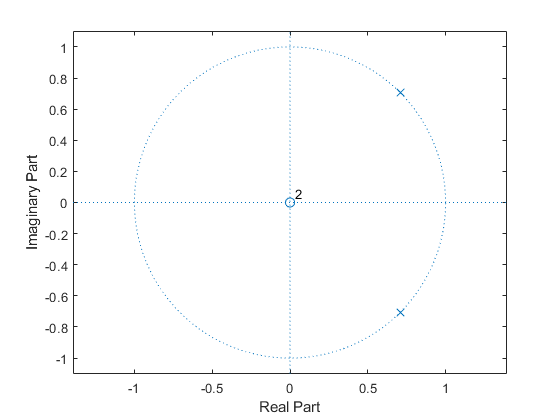

% norm(z(1)), norm(z(2))
% Verify that the poles are on the unit circle
zplane(1, eig_vec_min')

In general, the $z$ is defined as follows:

        
$$z=Ae^{\mathrm{j2}\pi f} =A\left\lbrack \mathrm{cos}\left(2\pi f\right)+j\;\mathrm{sin}\left(2\pi f\right)\right\rbrack$$


Recall that $\angle z=2\pi f$ and $f=\frac{\angle z}{2\pi }$ because of the definition of the complex number $z$:

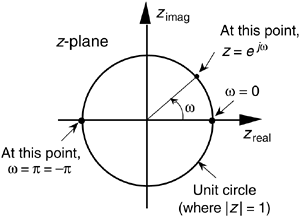

Since the two $z$ quantities that we found are on the unit circle, their magnitude $A=1$.

We also found that two pair of $z$s are complex conjucates of one another. So we only use one of them to compute the frequency:

f1 = abs(angle(z(2))) / (2*pi)

f1 = 0.1250

**Step 4:** Solve Eq. (14.5.11) for the signal powers $\left\lbrace P_i \right\rbrace$

        

Since we only have one frequency, the equation becomes:

        $\mathrm{cos}\left(2\pi f_1 \right)P_1 =\gamma_{\mathrm{yy}} \left(1\right)$ where $\gamma_{\textrm{yy}} \left(1\right)$ is the second autocorrelation value:

We want to find $P_1$:  

        
$$P_1 =\frac{\gamma_{\textrm{yy}} \left(1\right)}{\cos \left(2\pi f_1 \right)}$$
  

P1 = r_yy(2) / cos(2*pi*f1)

P1 = 1.4142

From section 14.5.1, we are given:

        
$$P_i =\frac{A_i^2 }{2}$$


This allows us to estimate the amplitude $A_i$ given $P_i$:

        
$$A_i =\sqrt{2P_i }$$


A1 = sqrt(2*P1)

A1 = 1.6818

All computation is captured in the `pisarenko(r_yy, p)` function. Let us verify:

[F, A] = pisarenko(r_yy, p)

F = 0.1250

A = 1.6818

## Exam 2012, Problem 3: PSD Estimation

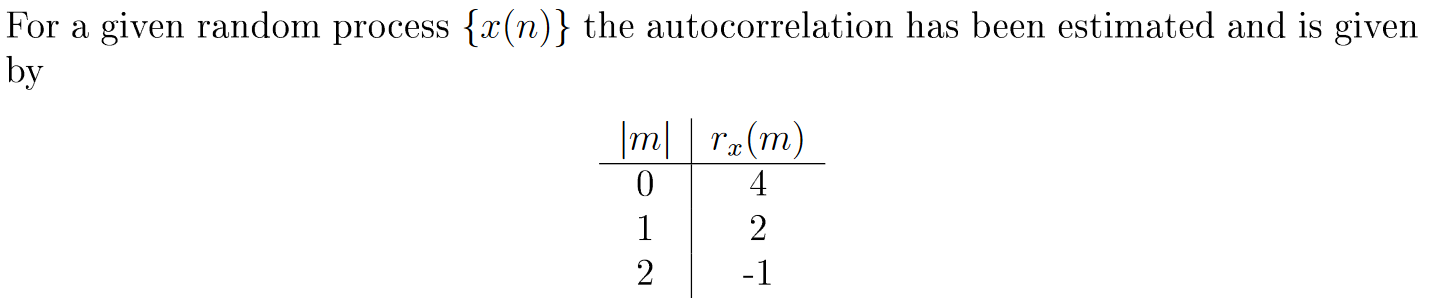

clear variables;

F = 0.1490

A = 2.5970

P = 3.3723

lambda_min = 0.6277

### 👀 1) Estimate PSD assuming sinusoidal white noise

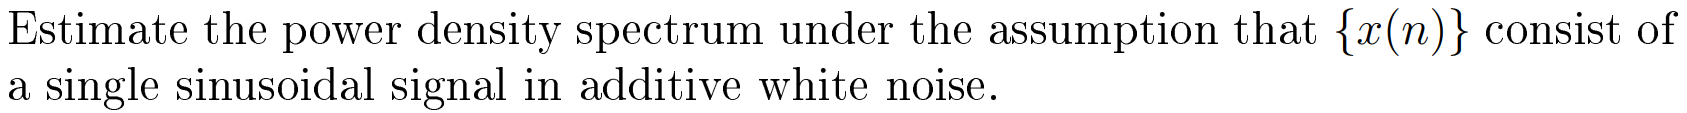

The Pisarenko method is used to estimate the power spectrum density of a random process. 

The method makes two assumptions:

- The signal $x\left(n\right)$ consists of $p$ sinusoids that has been corrupted by white noise.

- The autocorrelation matrix of size $\left(p+1\right)\times \left(p+1\right)$ is known or can be estimated

Given these assumptions, the Pisarenko method can recover the sinusoidal frequencies of the corrupted signal using the following steps:

***Step 1***: Compute the autocorrelation matrix ${\mathbf{R}}_{\mathrm{yy}}$

***Step 2:*** Find the eigenvector corresponding to the smallest minimum eigenvalue. The elements of this eigenvector is the parameters of the $\mathrm{ARMA}\left(2p,2p\right)$ model 

***Step 3:*** Find the frequencies $\left\lbrace \;f_i \;\right\rbrace$ of the sinusoids. This can be done by computing the roots of the polynomial $A\left(z\right)$ in (14.5.4). This polynomial has $2p$ poles on the unit circle which correspond to the frequencies of the system.

        

***Step 4*****:** Solve Eq. (14.5.11) for the signal powers $\left\lbrace P_i \right\rbrace$

        

where 

- $\gamma_{\mathrm{yy}} \left(1\right),\gamma_{\mathrm{yy}} \left(2\right),\cdots ,\gamma_{\mathrm{yy}} \left(p\right)$ are the estimated autocorrelation values 

- $P_i =\frac{A_i^2 }{2}$ is the average power of the $i$th sinusoid and $A_i$ is the corresponding amplitude

***Step 5***: Estimate the amplitude $A_i =\sqrt{2P_i }$

These steps are coded up in the `pisarenko()` function (see at end of this document):

r_xx = [4, 2, -1];
[F, A, P, lambda_min] = pisarenko(r_xx, 1)

ans =     2.6277   -0.3723   -2.5584


We can describe the signal as follows:

        
$$x\left(n\right)=2\ldotp 597\cdot \mathrm{cos}\left(2\pi \cdot 0\ldotp 149n+\phi \right)+w\left(n\right)$$


where $w\left(n\right)$ is white noise with variance $\sigma_w^2 =0\ldotp 6277$.

In ADSI Problem 4.4, we found that the autocorrelation of a real sinusoid given by $y\left(n\right)=A\;\mathrm{cos}\left(\omega n+\phi \right)$ where $A$ and $\omega$ are real constants and $\phi$ is a random variable with $\phi ~U\left(0,2\pi \right)$ is:

        
$$r_{\textrm{yy}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


The autocorrelation function of white noise with variance $\sigma_w^2$ is given by:

        
$$r_{\mathrm{ww}} \left(\ell \right)=\sigma_w^2 \delta \left(\ell \right)$$


Using these results, we have the autocorrelation function of the signal:

        
$$r_{\mathrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)+\sigma_w^2 \delta \left(\ell \right)$$


ell = 1:3;
(A^2/2) * cos(2*pi*F*ell) + lambda_min

ans = 10.5943

ans = 0.9359

**HELP: Is this correct? The given ACRS was [4, 2, -1]. Should we not get results close to this?**

The power spectral density is the Fourier transform the autocorrelation function:

        
$$S\left(\omega \right)=\frac{A^2 }{2}\pi \left\lbrack \delta \left(\omega -\omega_0 \right)+\delta \left(\omega +\omega_0 \right)\right\rbrack +\sigma_w^2$$


**HELP: Not sure if the Fourier transform is computed correct.**

Putting the values, we have:

        
$$S\left(\omega \right)=\frac{{\left(2\ldotp 597\right)}^2 }{2}\pi \left\lbrack \delta \left(\omega -2\pi \cdot 0\ldotp 149\right)+\delta \left(\omega +2\pi \cdot 0\ldotp 149\right)\right\rbrack +0\ldotp 6277$$


(A^2*pi)/2
2*pi*F

        
$$S\left(\omega \right)=10\ldotp 5943\left\lbrack \delta \left(\omega -0\ldotp 9359\right)+\delta \left(\omega +0\ldotp 9359\right)\right\rbrack +0\ldotp 6277$$


### 2) Estimate PSD assuming MA(2) process

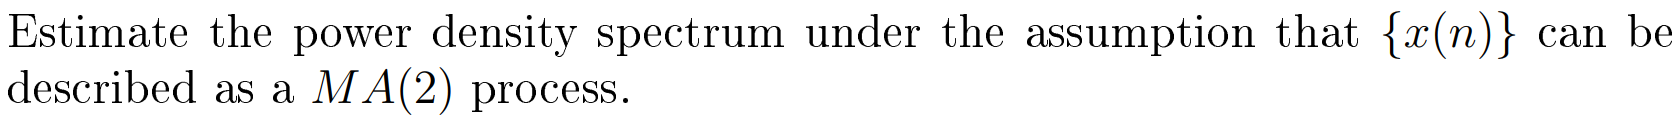

## Functions

function [F, A, P, lambda_min]=pisarenko(r_xx, p)
    % Estimates the frequencies and amplitudes using the Pisarenko method
    %  r_xx: autocorrelation sequence starting from zero. 
    %        The length of ACRS must be at least 2p+1.
    %  p: assumed number of sinusoids in the signal
    %  F: normalised frequencies of the sinuoids
    %  A: amplitudes of the sinuoids
    if numel(r_xx) < 2*p+1
        error(strcat('The length of ACRS must be at least ', int2str(2*p+1)));
    end
    
    % Compute the autocorrelation matrix
    R_xx = toeplitz(r_xx(1:2*p+1));
    
    % Perform the eigendecomposition
    [eigvecs, eigvals] = eigs(R_xx, size(R_xx, 1), 'smallestreal');
    
    eigvals = diag(eigvals);
    lambda_min = eigvals(1);
    
    % Find the eigenvector 'a' corresponding to the smallest eigenvalue.
    % The function eigs() sorts eigenvectors, so just pick the first column.
    a = eigvecs(:, 1);
    
    % Ensure that a_0 = 1 (this is by definition)
    a = a / a(1);
    
    % The elements of this eigenvector corresponds to the parameters
    % of an ARMA(2p, 2p) model: a_0, a_1, ..., a_2p where p: number of sinusoids
    % The polynomial A(z) in (14.5.4) has 2p poles on the unit circle.
    % Obtain the poles by finding the roots of the system.
    z = roots(a);
    
    % Estimate frequencies
    F = zeros(p, 1);
    for i = 1:p
        % The poles come in pairs. Each pair is complex conjugate
        % of one another. Only use one of them and find the absolute value.
        z_i = z(2*i);
        F(i) = abs(angle(z_i)) / (2*pi);
    end
    
    % Build the matrix of cosines
    C = zeros(p);
    for i = 1:p
        for j = 1:p
            C(i, j) = cos(i * 2*pi * F(j));
        end
    end
    
    % Start the ACRS from the second element according to equation (14.5.11)
    gamma = r_xx(2:p+1);
    
    % Solve equation (14.5.11) for P
    P = C\gamma; % Same as `inv(C)*gamma` but faster and more accurate
    
    % Since P=A^2/2, we can compute the amplitude A=sqrt(2*P)
    A = sqrt(2 * P);
end